# Lab 09 modeling acoustic systems

Brandon Tighe - MECH 529

03/31/2021

clc
clear

## Task 1- Engine output flow model

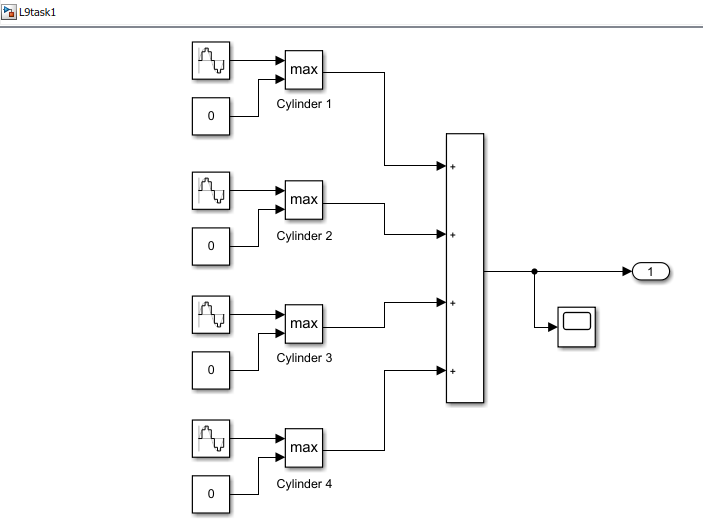

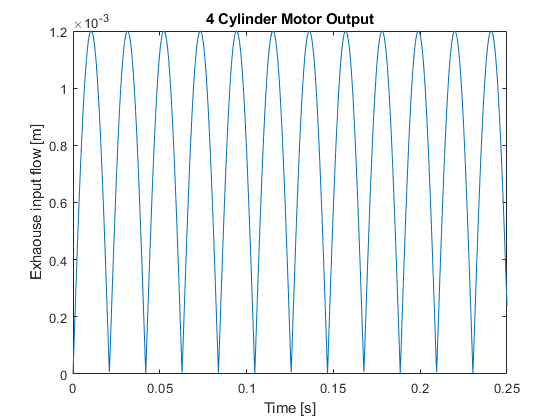

Q_cyl= .0006;           %Cylinder volume (amplitude)
omega_eng = 150;     %frequency

open_system('L9task1');
load_system('L9task1');
sim('L9task1');
figure(1)

%plot(ans.simout1)
plot(ans.ScopeData(:,1),ans.ScopeData(:,2))
title('4 Cylinder Motor Output')
xlabel('Time [s]')
ylabel('Exhaouse input flow [m]')

## Task 2- Exhaust System Model Without Muffler

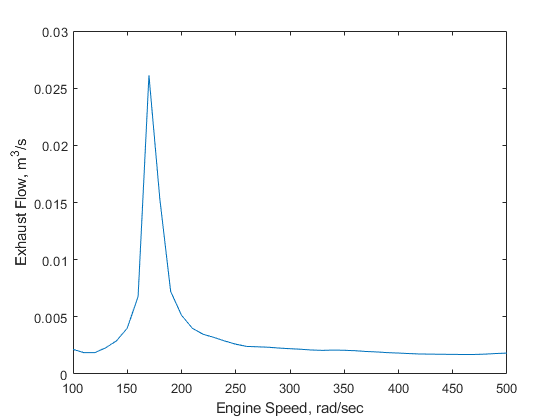

% Given variables/ equations
rho = 1.18;     % kg/m3
S = pi*0.01^2;  %crosssect. area m2
Beta = 1.42e5;  % bulk mod. of air
L_pipe = 1 ;    %meters
I_pipe = rho*L_pipe/S;
C_pipe = L_pipe*S/Beta; 


i=0;
for omega_eng = 100:10:500
 i=i+1;
 sim('L9task2');
 omega_eng_out(i) = omega_eng;
 q_out_max(i) = max(ans.ScopeData3(:,2));
 q_out_avg(i) = mean(ans.ScopeData3(:,2));
end
figure; plot(omega_eng_out, q_out_max) 
xlabel('Engine Speed, rad/sec')
ylabel('Exhaust Flow, m^3/s')

## Task 3- Muffler design homework P1

Resistance muffler

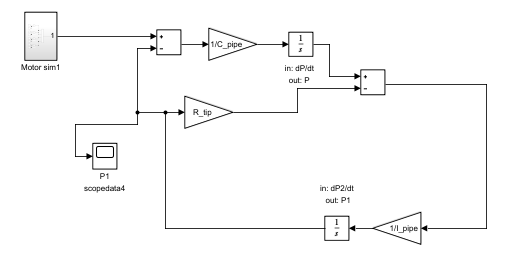

Reactive muffler

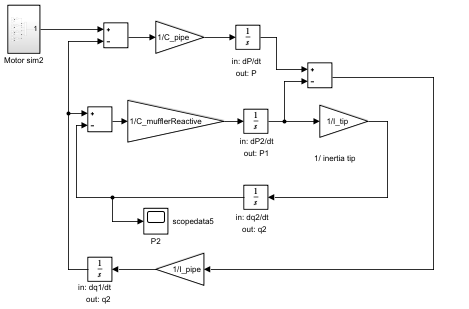

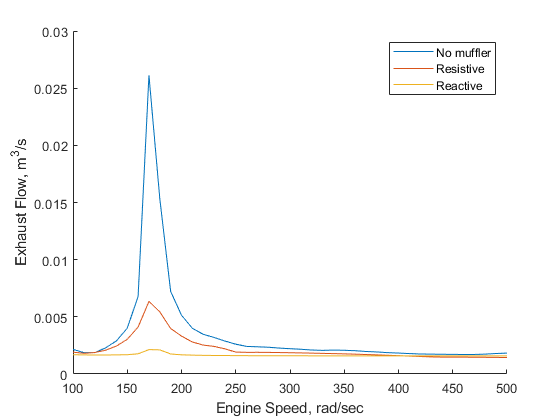

% Given variables/ equations
rho = 1.18;     % kg/m3
S = pi*0.01^2;  %crosssect. area m2
Beta = 1.42e5;  % bulk mod. of air
L_pipe = 1 ;    % meters
I_pipe = rho*L_pipe/S;
C_pipe = L_pipe*S/Beta; 

eta= 1.702e-5;  % Viscosity
L_tip= .5;      % [m]
a = .001;       % tip pipe diameter

R_tip= ((8*eta*L_tip)/(pi*(a^4)))/200;
C_mufflerResist=  L_pipe*S/Beta;

%--------------------------------
Lmuff= .1;
Radmuff= .25;
Ltip= .5; 
%=================================

Smuff= pi*Radmuff^2 ;
C_mufflerReactive= Lmuff*Smuff/Beta;
I_tip = rho*Ltip/S;

i=0;
for omega_eng = 100:10:500
 i=i+1;
 sim('L9task3');
 omega_eng_out(i) = omega_eng;
 
%  %no muffler
%  q_out_max(i) = max(ans.ScopeData2(:,2));
%  q_out_avg(i) = mean(ans.ScopeData2(:,2));
%  
 %resistive muffler
 q_out_max1(i) = max(ans.ScopeData4(:,2));
 q_out_avg1(i) = mean(ans.ScopeData4(:,2));
 
 %Reactive muffler 
 q_out_max2(i) = max(ans.ScopeData5(:,2));
 q_out_avg2(i) = mean(ans.ScopeData5(:,2));

end
figure; 
hold on
plot(omega_eng_out, q_out_max,'DisplayName','No muffler') 
xlabel('Engine Speed, rad/sec')
ylabel('Exhaust Flow, m^3/s')
plot(omega_eng_out, q_out_max1,'DisplayName', 'Resistive') 
plot(omega_eng_out, q_out_max2,'DisplayName','Reactive') 
legend
hold off

This plot shows that the resistive muffler has a very large effect on exhause flow (and hence sound), but the reactive muffler

 is clearly the best choice for exhaust noise reduction. 

## Task 3- Homework P2

The natural frequencies were calculated using the following equation:

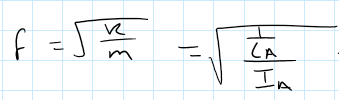

Natural_Frequency_No_Muffler = sqrt((1/C_pipe)/I_pipe)

Natural_Frequency_No_Muffler = 346.8991

Natural_Frequency_Muffler=sqrt((1/C_mufflerReactive)/I_tip)

Natural_Frequency_Muffler = 62.0552

To avoid a harmonic occurance, the natural frequency of the muffler must not be an integer ratio with the natural frequency of the motors output

Frequency_ratio= Natural_Frequency_No_Muffler/Natural_Frequency_Muffler

Frequency_ratio = 5.5902

The ratios between the frequencies is not an integer. 